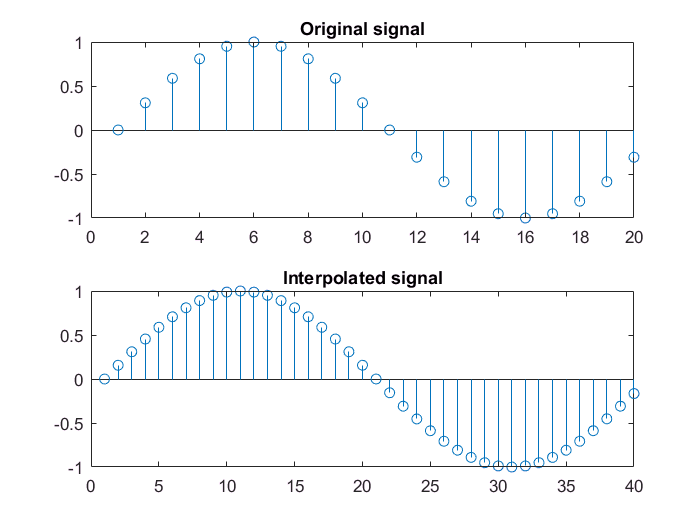

F=input('Enter the frequency of the signal: ');
P=input('Enter the interpolator factor: ');
N=input('Enter the length of the signal: ');
 
t=0:1:N-1;
X = sin(2*pi*F*t);
subplot(2,1,1);
stem(X);
title("Original signal");
 
i=interp(X,P);
subplot(2,1,2);
stem(i);
title("Interpolated signal");

%another way
clc;
clear all;
close all;

% Program for illustration of interpolation process
N = input('Enter the length input signal = ');
L = input('Enter the interpolation factor = ');
f1 = input('Enter the value of frequrncy for the first sinusoidal component = ');
f2 = input('Enter the value of frequency for the second sinusoidal component = ');

% Generate the input discrete-time signal

n = 0:N-1;
x = sin(2*pi*f1*n)+sin(2*pi*f2*n);

% Generation of interpolated signal
y = interp(x,L);

% Plot the input and output sequences
subplot(2,1,1);
stem(n,x(1:N));
xlabel('Time index n');
ylabel('Amplitude');
title('Input discrete time sequence');

subplot(2,1,2);
m = 0:N*L-1;
stem(m,y(1:N*L));
xlabel('Time index n');
ylabel('Amplitude');
title('Output Interpolated Sequence');
